# Exploratory Mood 

### Here we will check to see if our code does justice to images from internet and on two of our group mates. 

% load cifar10testdata for getting the class labels
load 'cifar10testdata.mat'

Display sample image

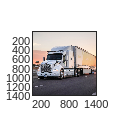

% truck sample image from theverge website
% https://www.theverge.com/_next/image?url=https%3A%2F%2Fcdn.vox-cdn.com%2Fthumbor%2F7_52ecX80GVrd4tYPsIysvTpGSg%3D%2F0x0%3A4243x3079%2F2000x1333%2Ffilters%3Afocal(2122x1540%3A2123x1541)%2Fcdn.vox-cdn.com%2Fuploads%2Fchorus_asset%2Ffile%2F18980526%2FTuSimple_Self_Drving_Truck_4_copy.jpg&w=640&q=75
imrgb = imread("truck1.jpg");
figure; imagesc(imrgb); truesize(gcf,[64 64]);

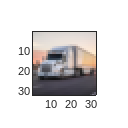

%% We implement downsampling to make the data of a more manageable size and reduce the dimensionality of the data thus enabling in faster processing of the data
% Downsampling the input truck image 
% here we are using bilinear approximation to resize)
imrgb = imresize(imrgb,[32, 32],'Method','bilinear');
figure; imagesc(imrgb); truesize(gcf,[64 64]);

%% forward pass refers to calculation process, values of the output layers from the inputs data. It's traversing through all neurons from first to last layer.
% run forward pass on the CNN model with input image 
import model.*
m = model();
output = m.forward(imrgb);
convertProbToLabel(output, classlabels);

MODEL OUTPUT RESULT : estimated class is truck with probability 0.3364


### Running CNN model on our group mates

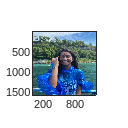

imrgb = imread("nandinee.jpg");
figure; imagesc(imrgb); truesize(gcf,[64 64]);

Downsampled image

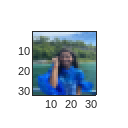

imrgb = imresize(imrgb,[32, 32],'Method','bilinear');
figure; imagesc(imrgb); truesize(gcf,[64 64]);

%% the probabilities are converted to labels for ease in classification
output = m.forward(imrgb);
[~,~] = convertProbToLabel(output, classlabels);

MODEL OUTPUT RESULT : estimated class is ship with probability 0.3435


Running the model on another group mate

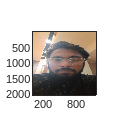

imrgb = imread("srijit.jpg");
figure; imagesc(imrgb); truesize(gcf,[64 64]);

Downsampled image

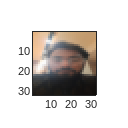

imrgb = imresize(imrgb,[32, 32],'Method','bilinear');
figure; imagesc(imrgb); truesize(gcf,[64 64]);

output = m.forward(imrgb);
[~,~] = convertProbToLabel(output, classlabels);

MODEL OUTPUT RESULT : estimated class is cat with probability 0.3398


### Unknown Category

One approach to allow for unknown categories is to use a threshold value on output probability.

i.e., take the maximum probability (p) from the softmax output and check if that probability is greater than a threshold value (we can take a threshold value of 0.3).

modified_classifier = { 

                        if p > threshold_value             :        output label corresponding to 'p'

                        else                                        :         output label as 'unknown'

}

function [maxprob,maxclass] = convertProbToLabel(inputProb, classlabels)
    %find most probable class
    %squeeze returns an array with the same elements as the input probability array, but with dimensions of length 1 removed
    classprobvec = squeeze(inputProb);
    [maxprob,maxclass] = max(classprobvec);
    fprintf('MODEL OUTPUT RESULT : estimated class is %s with probability %.4f\n',...
classlabels{maxclass},maxprob);
end